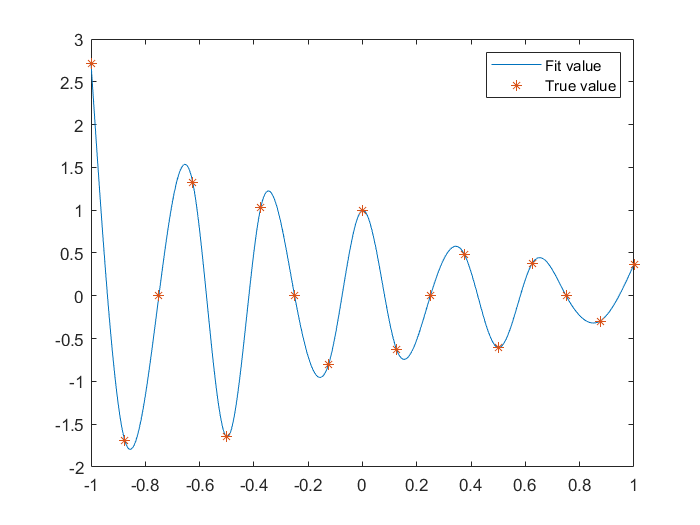

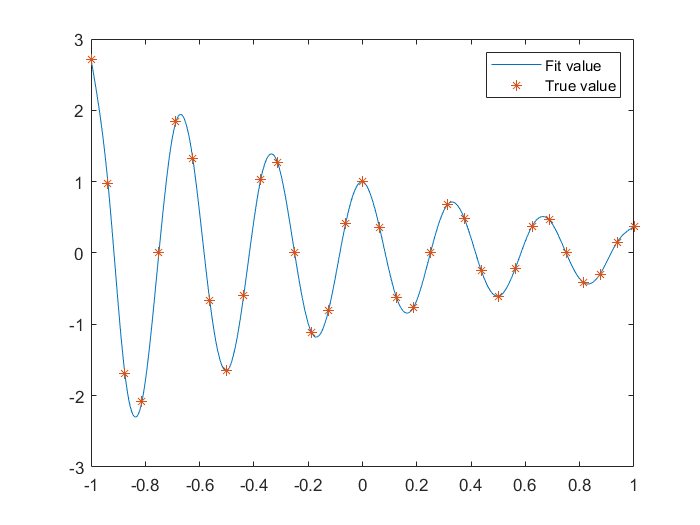

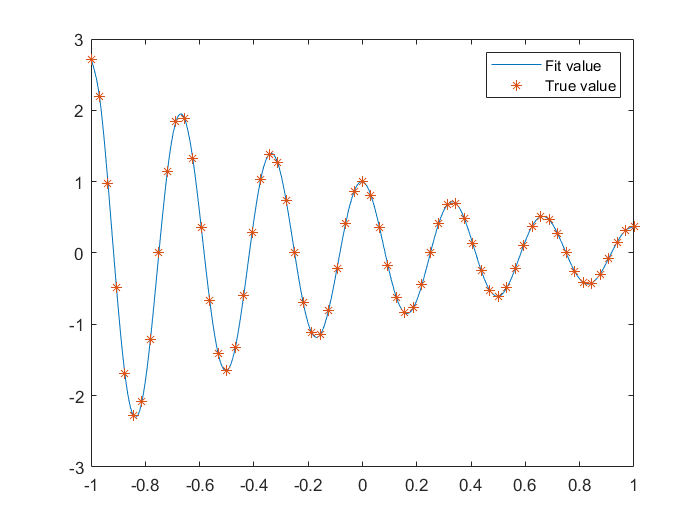

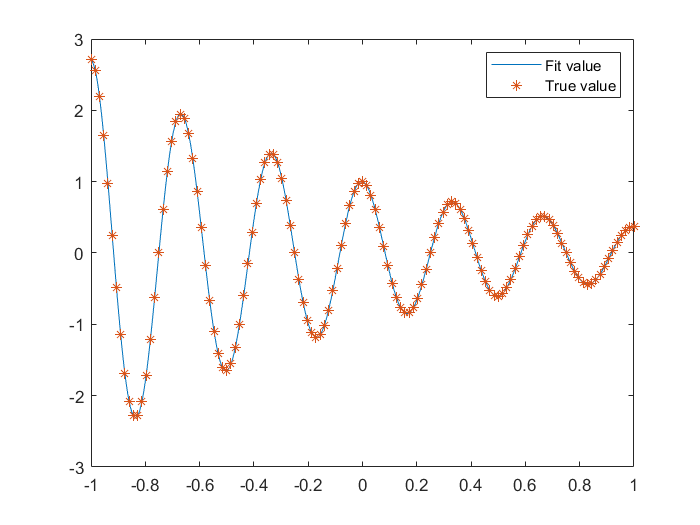

clc,clear,close all
nn = [16,32,64,128];
my_error = zeros(1,length(nn));
for i = 1:4
    n = nn(i);
    x = linspace(-1,1,n+1);
    f = exp(-x).*cos(6*pi*x);
    c = get_coefficients(f);
    yy = get_yy(x,c);
    a = x(1);
    b = x(end);
    xx = linspace(a,b,20*(n+1)+1);
    figure
    plot(xx,yy)
    hold on
    plot(x,f,'*')
    hold off
    legend('Fit value','True value')
    my_error(i) = max(abs(yy-exp(-xx).*cos(6*pi*xx)));
end

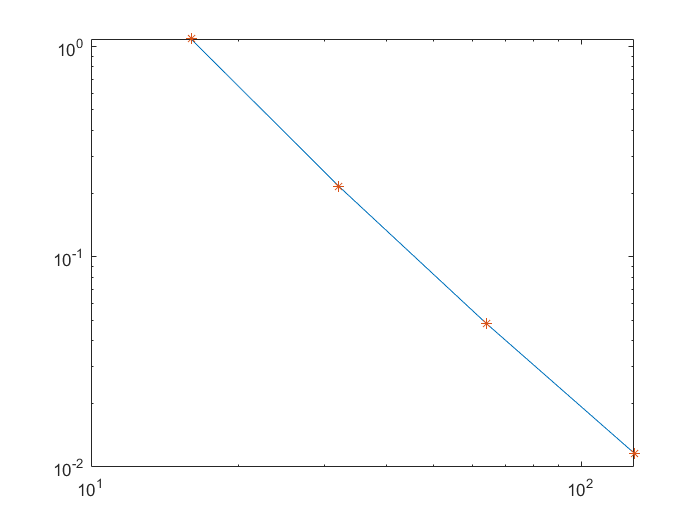

loglog(nn,my_error)